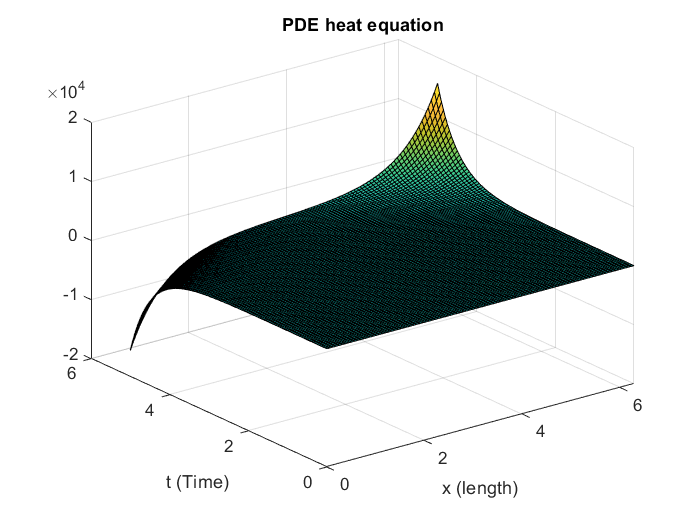

m = 0;
t = linspace(0, 5, 100);
x = linspace(0, 2*pi, 100);
u = pdepe(m , @pdefun, @icfun, @bcfun, x, t);
surf(x, t, u);
title("PDE heat equation");
xlabel("x (length)");
ylabel("t (Time)");

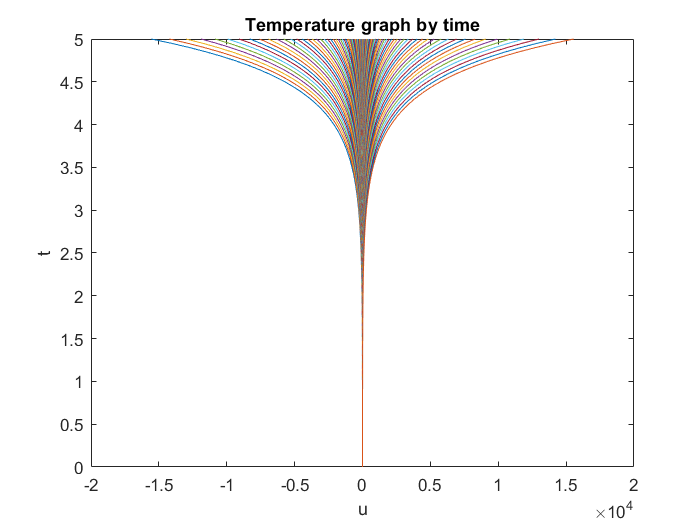

plot(u, t);
title("Temperature graph by time");
xlabel("u");
ylabel("t");

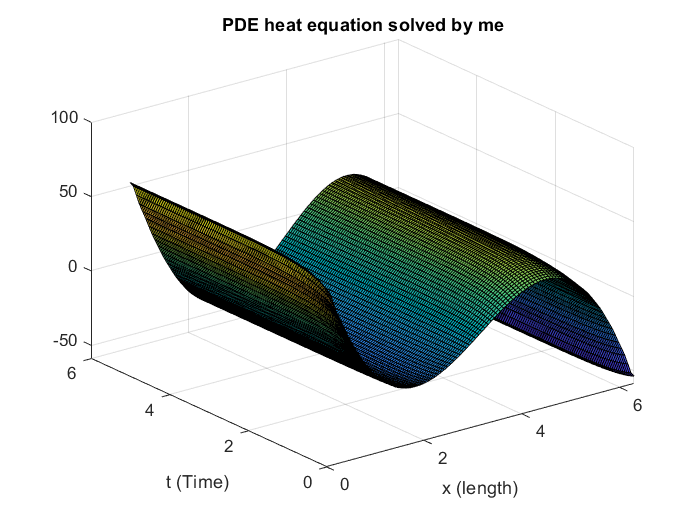

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[x1, t1] = meshgrid(x, t);
s = 0;
for n = 2:50
s = s + (-4*(((-1)^n)-1)*(n^2+1)/(pi*n^2*(n^2-1))+(8*exp(-2*t1)*(((-1)^n)-1))/(pi*n^2*(n^2-1)))*cos(n*x1/2);
end
s = s + x1*exp((-2*t1)) - pi*exp(-2*t1);
surf(x1, t1, s);
title("PDE heat equation solved by me");
xlabel("x (length)");
ylabel("t (Time)");

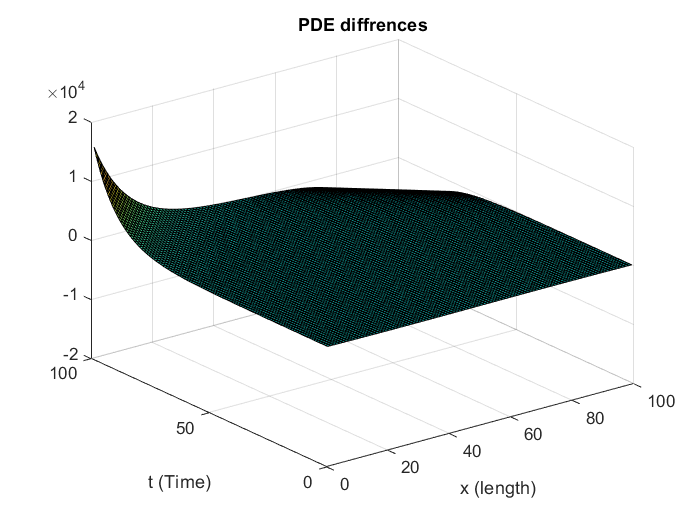



surf(s-u);
title("PDE diffrences");
xlabel("x (length)");
ylabel("t (Time)");

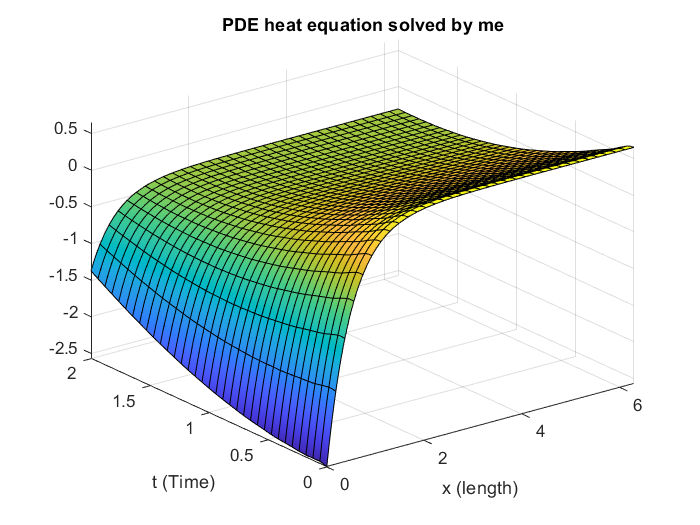


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x = linspace(0, 2*pi, 100);
t = linspace(0, 2, 100);
syms n x t 
k = symsum((-4*(((-1)^n)-1)*(n^2+1)/(pi*n^2*(n^2-1))+(8*exp(-2*t)*(((-1)^n)-1))/(pi*n^2*(n^2-1)))*cos(n*x/2)  , n , 2, 50);
k = k + x*exp((-2*t)) - pi*exp(-2*t);
syms x t 
fsurf(k, [0 2*pi 0 2]);
title("PDE heat equation solved by me");
xlabel("x (length)");
ylabel("t (Time)");